# Estrazione di feature tramite AlexNet, ResNet e VGG16

## Flag di configurazione

Variabili che permettono l'esecuzione selettiva del codice e scelta di alcuni parametri come la rete da utilizzare.

% === VARIABILI DI STAMPA ================== %
printTrainingSet = 1;
printTestSet = 1;
printConfMatr = 1;

% === CONCATENAZIONE ======================= %
concatenationMetadata = 1;
normalizationMetadata = 1;

% === ALTRE VARIABILI ====================== %
% network = "alexnet";
% network = "resnet18";
% network = "resnet50";
network = "vgg";

## Caricamento dei dati

Per l'esecuzione di questi esperimenti sarà necessario avere soltanto **training set** e **test set**, il validation set rimarrà inutilizzato. 

Le label di classe sono prese dal nome della cartella di appartenenza tramite la funzione `imageDatastore()`.

imdsTrain = imageDatastore('dataset/TrainSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('dataset/TestSet','IncludeSubfolders',true,'LabelSource','foldernames');
numTrainImages = numel(imdsTrain.Labels)

numTrainImages = 162770

numTestImages = numel(imdsTest.Labels)

numTestImages = 19962

## Dominio

Stampa casuale di alcune delle immagini appartenenti al training set

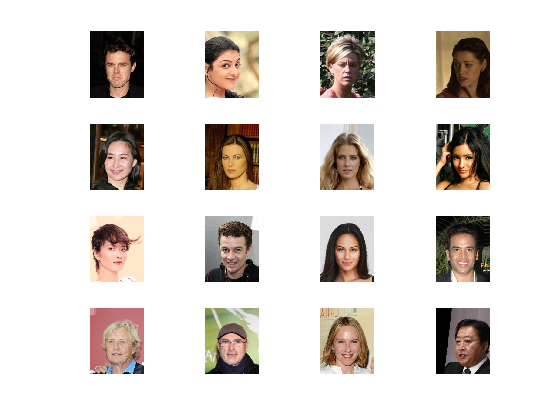

if printTrainingSet == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end
end

## Caricamento della rete e scelta del layer di attivazione

In base alla scelta della rete da caricare (scelta nel primo blocco) questa viene caricata e viene scelto il layer di attivazione. 

I layer più profondi contenfono features di alto livello, costruite usando le feature di basso livello dei layer precedenti. Per avere una rappresentazione delle feature delle immagini del train e del test set, il programma utilizzerà `activations` su differenti layer In base alla rete utlizzata.

Nel nostro caso:

- **alexnet**: **fc7**

- **resnet18**: **pool5**

- **resnet50: fc1000**

- **vgg16**: **fc7**

Questi parametri possono essere cambiati. Quello che vogliamo fare è sostanzialmente estrapolare le feature dall'ultimo livello prima che la rete classifichi.

tic; % init timer

if network == "alexnet"
    net = alexnet;
    layer = 'fc7';
    env = 'gpu';
elseif network == "resnet18"
    net = resnet18;
    layer = 'pool5';
    env = 'multi-gpu';
elseif network == "resnet50"
    net = resnet50;
    layer = 'fc1000';
    env = 'gpu';
else
    net = vgg16;
    layer = 'fc7';
    env = 'gpu'
end

env = 'gpu'

## Ridimensionamento immagini

Ogni rete richiede una dimensione diversa delle immagini, quindi viene fatto il resize per renderle conformi alle specifiche della rete.

Per fare il ridimensionamento automatico delle img viene utilizzato augmentedImageDatastore() a cui vengono passati come parametri le dimensioni che devono avere le img e le img originali, dopodiché le img originali non verranno più utilizzate.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

## Estrazione delle feature

Vengono estratte le feature dal train e test set (passati come input) utilizzando il network e layer selezionati nella parte precedente. Poi vengono salvate in una variabile le etichette del train e test set utili nella classificazione che verrà effettuata successivamente.

featuresTrain1 = activations(net,augimdsTrain,layer,'OutputAs','rows','ExecutionEnvironment',env);
featuresTest1 = activations(net,augimdsTest,layer,'OutputAs','rows','ExecutionEnvironment',env);
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;


## Concatenazione metadata feature

Concatenazione delle feature presenti nel dataset a quelle estrattes

if concatenationMetadata == 1
    featTrainMatrix = readmatrix('dataset/TrainSet_features.txt', 'Delimiter', ' ');
    featTestMatrix = readmatrix('dataset/TestSet_features.txt', 'Delimiter', ' ');

    featuresTrain1 = [featuresTrain1, featTrainMatrix];
    featuresTest1 = [featuresTest1, featTestMatrix];

    if normalizationMetadata == 1
        [featuresTrain1, C, S] = normalize(featuresTrain1);
        featuresTest1 = normalize(featuresTest1, 'center', C, 'scale', S);
    end
end

## Classificazione

Viene utilizzata una SVM per eseguire la classificazione.

Prima viene fatta la conversione per poter rendere i dati compatibili con con "liblinear", successivamente viene addestrato il modello sul training set passandogli le etichette e le features.

Come ultima cosa viene utilizzato il modello sul test set per misurarne l'accuratezza.

YTrain = double(YTrain(:,1));
YTest = double(YTest(:,1));
featuresTrain = sparse(double(featuresTrain1));
featuresTest = sparse(double(featuresTest1));
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'MaxEpochs',10, ...
    'MiniBatchSize',128, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','multi-gpu');
model = train(YTrain, featuresTrain, options, '-s 2');

init f 1.628e+05 |g| 5.641e+06
iter  1 f 6.142e+04 |g| 9.549e+05 CG   2 step_size 1.00e+00 
iter  2 f 3.367e+04 |g| 4.201e+05 CG   8 step_size 1.00e+00 
iter  3 f 3.095e+04 |g| 1.697e+05 CG   2 step_size 1.00e+00 
iter  4 f 2.289e+04 |g| 1.175e+05 CG   8 step_size 1.00e+00 
iter  5 f 1.930e+04 |g| 5.720e+04 CG  10 step_size 1.00e+00 
iter  6 f 1.758e+04 |g| 2.646e+04 CG  10 step_size 1.00e+00 
iter  7 f 1.649e+04 |g| 1.585e+04 CG  15 step_size 1.00e+00 


YPred = predict(YTest, featuresTest, model);

Accuracy = 96.6436% (19292/19962)


## Risultati predizione

Stampa di alcune img del test set con associata la label predetta e quella corretta.

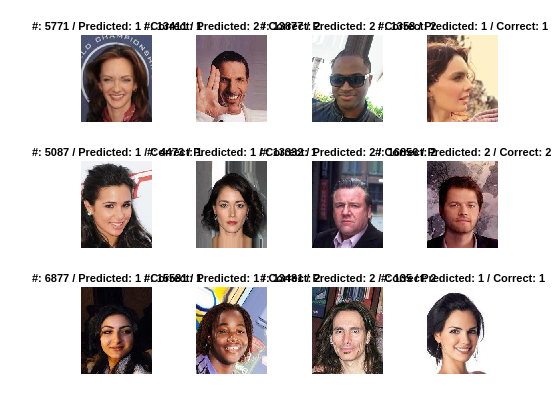

if printTestSet == 1
    idx = randi([1 numTestImages],1,12);
    figure
    for i = 1:numel(idx)
        subplot(3,4,i)
        I = readimage(imdsTest,idx(i));
        label = YPred(idx(i));
        corr = YTest(idx(i));
        imshow(I)
        title("#: "+idx(i)+" / Predicted: "+label+" / Correct: "+corr)
    end
end

## Matrice di confusione

Stampa della matrice di confusione. Ogni colonna della matrice rappresenta i valori predetti **(Output Class)** ed ogni riga rappresenta i valori reali **(Target Class)**.

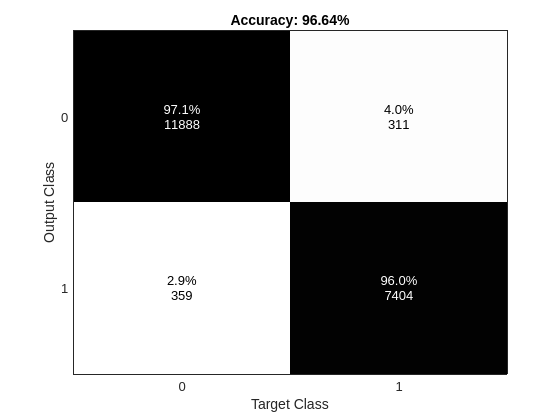

if printConfMatr == 1
    cm = confusionmat(YPred,YTest);
    labels = {0,1};
    figure
    plotConfMat(cm,labels)
end

## Conclusioni

I risultati raggiunti sono espressi tramite accuratezza e rapporto fra i veri positivi sul numero totale di immagini. Come informazione aggiuntiva abbiamo il tempo che è stato impiegato per effettuare l'intero esperimento.

time = toc;
diff = numel(find(YPred~=YTest));
[M,N] = size(YPred);
tp = M-diff;
accuracy = round(mean(YPred == YTest)*100,2);
disp('Accuracy: '+string(accuracy)+"% - Time Elapsed: "+time+" s - True Positive vs Total: "+tp+"/"+M);

Accuracy: 96.64% - Time Elapsed: 710.436 s - True Positive vs Total: 19292/19962
